% Justina Korsun
% EEF-25/1

% 1 užduotis
clear
close all

C = cell(2 , 2);
C{1, 1} = [1 2; 3 4];
C{1, 2} = [5 6 7; 8 9 10];
C{2, 1} = [11 12; 13 14; 15 16];
C{2, 2} = [17 18 19; 20 21 22; 23 24 25];

cellfun(@length, C)

ans =      2     3
     3     3


cellfun(@isreal, C)

ans = 2×2 logical array
   1   1
   1   1


isempty(C)

ans = logical
   0


cellfun(@(x) isa(x, 'double'), C)

ans = 2×2 logical array
   1   1
   1   1


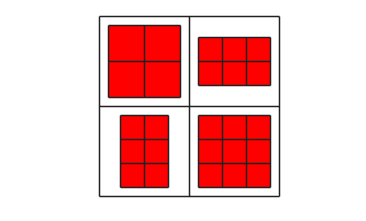


figure
cellplot(C)



M = cell2mat(C)

M =      1     2     5     6     7
     3     4     8     9    10
    11    12    17    18    19
    13    14    20    21    22
    15    16    23    24    25


m = 2

n = 2

     2     5
     3     6



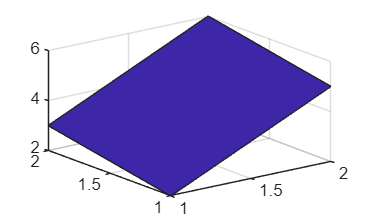

% Srauto valdymo konstruktoriai
clear
clc
close all

while true
    clear A
    m = input('m reiksme: ')
    n = input('n reiksme: ')

    A = zeros(m, n);

    for i = 1:m
        for j = 1:n
            A(i, j) = i + j^2;
        end
    end

    disp(A)

    figure
    surf(A)

    if m == n
        break
    end
end

%papildoma

clear
clc
close all

x = input('x reiksme: ');
y = input('y reiksme: ');

A = zeros(x, y);

for k = 1:15
    m = ceil(rand * x);
    n = ceil(rand * y);

    A(:) = 0;

    A(m, n)= NaN;

    disp(A)

    pause(0.5);
    clc;
end

     0   NaN
     0     0

     0     0
     0   NaN

   NaN     0
     0     0

     0   NaN
     0     0

     0   NaN
     0     0

   NaN     0
     0     0

   NaN     0
     0     0

     0     0
     0   NaN

     0     0
   NaN     0

     0     0
     0   NaN

     0   NaN
     0     0

   NaN     0
     0     0

   NaN     0
     0     0

   NaN     0
     0     0

   NaN     0
     0     0

